使用**粒子群算法**对FOPID的参数进行调节。

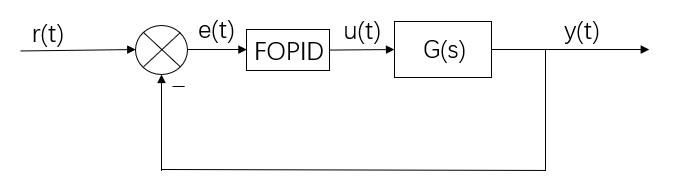

闭环控制

误差e=y-r，计算均方误差mse作为粒子的适应度。

clc
clear
close all

% 定义被控系统
global Wn zeta
Wn = 1;         % 固有频率 1rad/s
zeta = 0.5;     % 欠阻尼
Num = [Wn^2];
Den = [1, 2*zeta*Wn, Wn^2]; 

sys = tf(Num, Den)

sys =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



pole(sys)       % 系统有两个具有负实部的极点，系统稳定

ans =   -0.5000 + 0.8660i
  -0.5000 - 0.8660i



% 生成参考信号
global tau T X0 h t r
tau = 10;
Tmax = 50;
X0 = [0;0];
h = 0.01;
T = 0:h:Tmax;
[r,t] = gensig('square',tau, Tmax, h);  % 参考信号

第 1 次迭代：


当前全局最佳参数：

    1.8190    1.3075    4.4335    0.3372    0.8566



当前全局最佳mse：3.412571e-02 


当前全局最佳参数：

    1.8179    1.5905    4.6652    0.5956    0.9025



当前全局最佳mse：2.898056e-02 


当前全局最佳参数：

    2.0066    1.8421    4.8001    0.6279    1.1675



当前全局最佳mse：2.526490e-02 


第 2 次迭代：


当前全局最佳参数：

    1.9974    1.8127    4.8893    0.5591    1.2212



当前全局最佳mse：2.489207e-02 


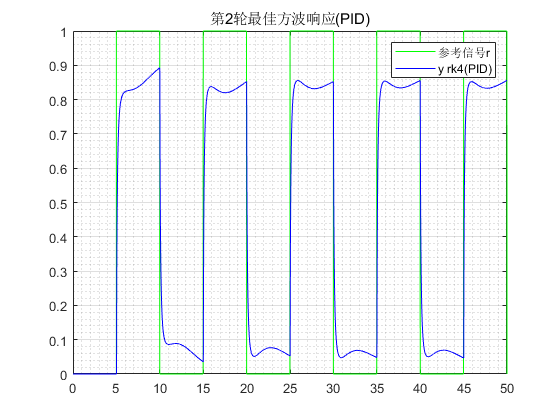

第 3 次迭代：


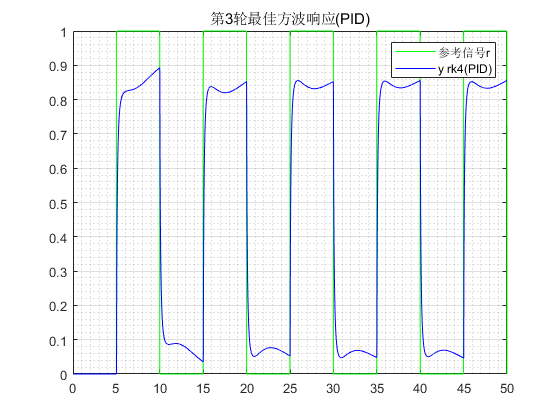

第 4 次迭代：


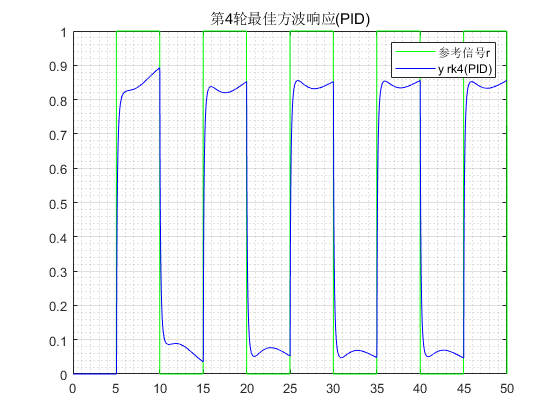

第 5 次迭代：


当前全局最佳参数：

    2.4867    2.4785    3.5792    0.6925    1.4263



当前全局最佳mse：2.418936e-02 


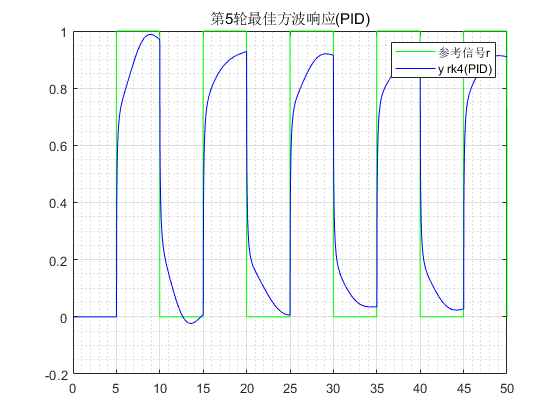

第 6 次迭代：


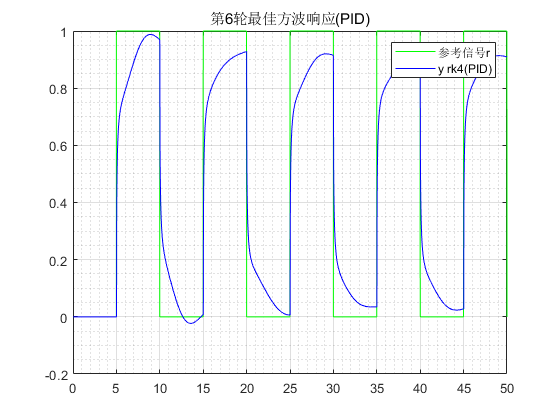

第 7 次迭代：


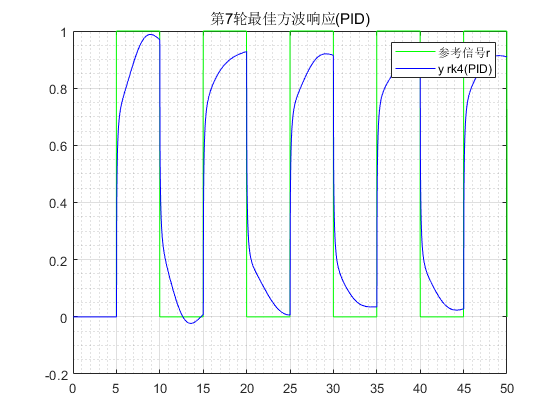

第 8 次迭代：


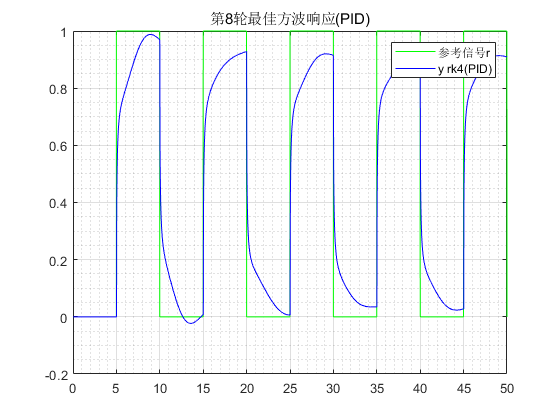

第 9 次迭代：


当前全局最佳参数：

    2.1748    2.0544    4.8009    0.5941    1.2871



当前全局最佳mse：2.395185e-02 


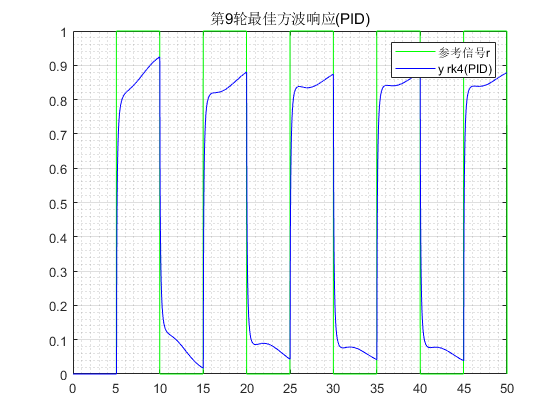

第 10 次迭代：


当前全局最佳参数：

    2.2503    2.2462    4.5048    0.5700    1.3901



当前全局最佳mse：2.338736e-02 


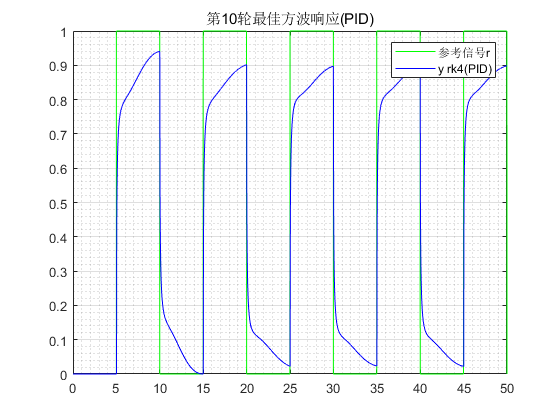

第 11 次迭代：


当前全局最佳参数：

    2.3597    2.2943    4.4871    0.6016    1.4316



当前全局最佳mse：2.324026e-02 


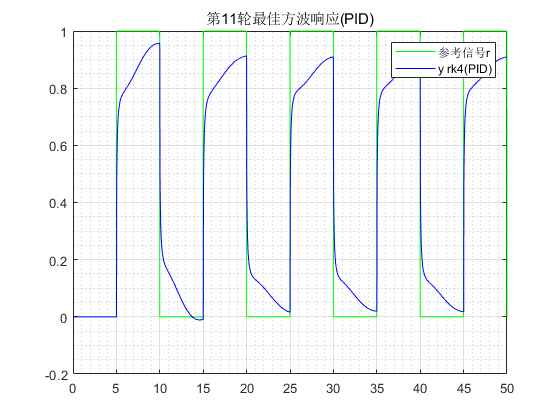

第 12 次迭代：


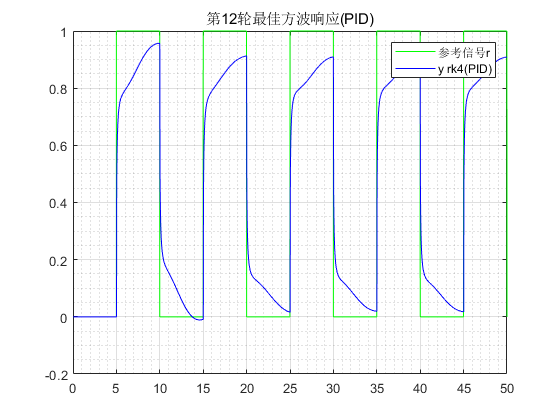

第 13 次迭代：


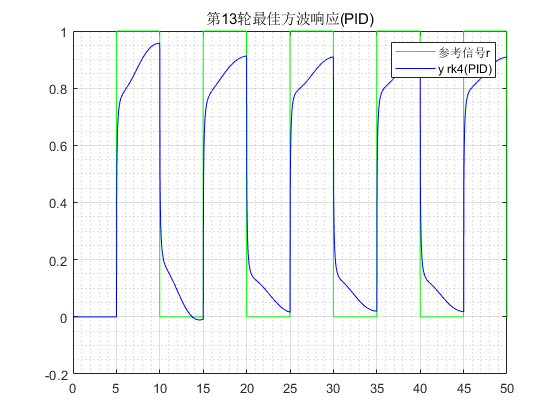

第 14 次迭代：


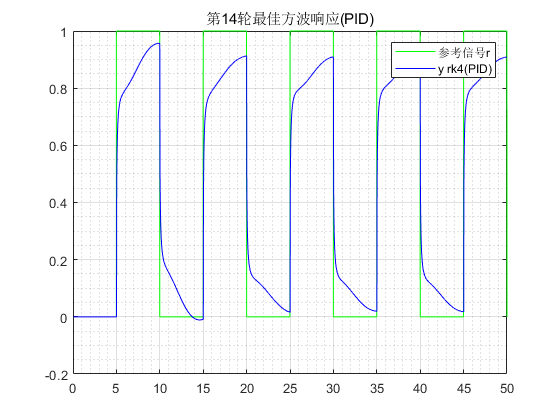

第 15 次迭代：


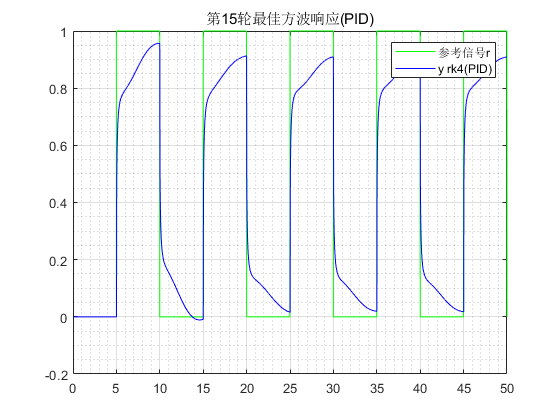

第 16 次迭代：


当前全局最佳参数：

    2.4008    2.3741    4.5282    0.6286    1.4221



当前全局最佳mse：2.308145e-02 


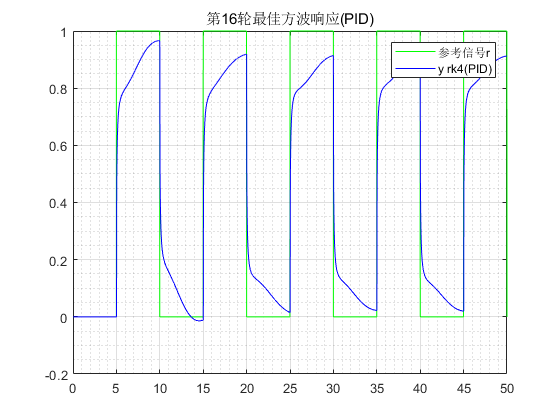

第 17 次迭代：


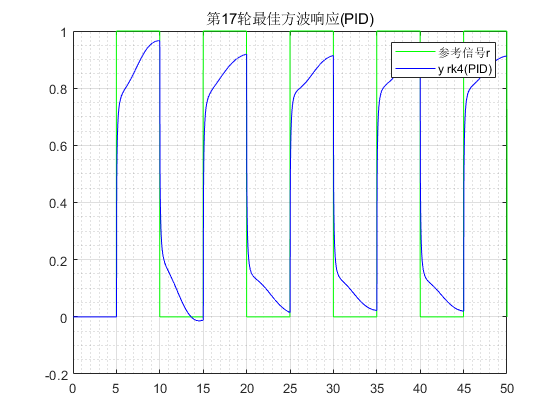

第 18 次迭代：


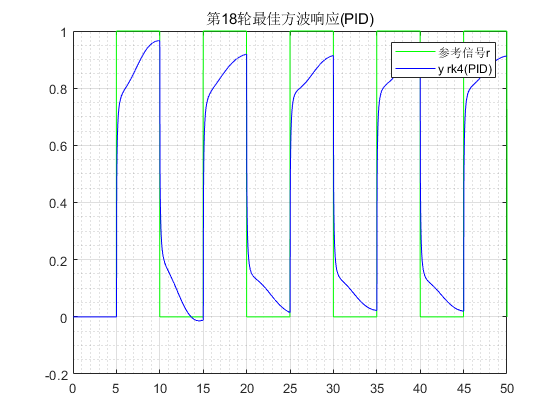

第 19 次迭代：


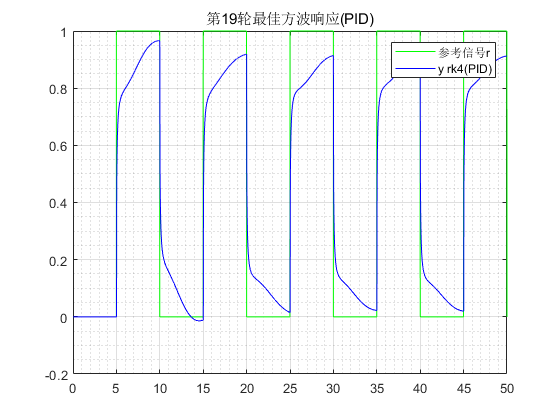

第 20 次迭代：


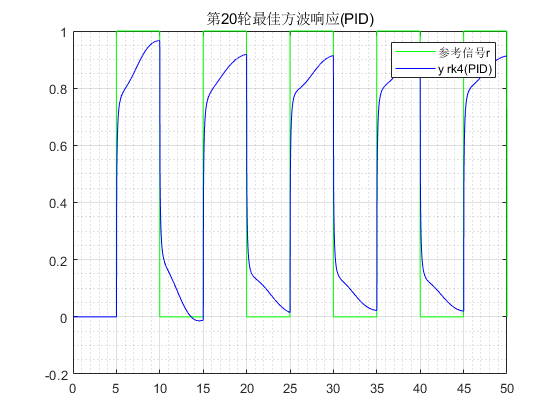

% 粒子群算法
% 参考：《智能优化算法及其MATLAB实例（第2版）》by包子阳 P121 例6.1
%%%%%%%%%%%%%%%% 粒子群算法初始化 %%%%%%%%%%%%%%%
N = 20;     % 粒子个数        
D = 5;      % 粒子维数
epoch = 20; % 迭代轮数       
Xmax = 5;
Xmin = 0;
Vmax = 0.5;
Vmin = -0.001;

%%%%%%%%%%%%%%%%% 初始化种群个体 %%%%%%%%%%%%%%%
% x = randi([Xmin, Xmax],N,D);
% v = randi([Vmin, Vmax],N,D);
x = unifrnd(Xmin, Xmax,[N,D]);
v = unifrnd(Vmin, Vmax,[N,D]);

%%%%%%%%%%%% 初始化最优位置和最优值 %%%%%%%%%%%
p = x;              % 每个粒子的历史最优位置
pbest = ones(N,1);  % 每个粒子的历史最优值

g = ones(1,D);      % 迭代过程中的最优粒子
gbest = inf;
gbest_input = 0;
gbest_output = 0;
for i = 1:N
    [pbest(i), input, output] = calculate(x(i,:));
    if pbest(i) < gbest
        g = p(i,:);
        gbest = pbest(i);
        gbest_input = input;
        gbest_output = output;
    end
end
gb = ones(1,epoch);

%%%%%%%%%%%%%%%%%%%% 迭代搜索参数 %%%%%%%%%%%%%%%%%%%%
for i = 1:epoch
    fprintf('第 %d 次迭代：\n', i);
    for j = 1:N
        %%%%%%%%%%%%%%%%%%%% 个体位置和速度更新 %%%%%%%%%%%%%%%%%%%%
        % Vjd(t+1) = w*Vjd(t)+ c1r1(t)[pjd(t)-Xjd(t)]+ c2r2(t)[pgd(t)-Xjd(t)]
        % Xjd(t+1) = Xjd(t) + Vjd(t+1)
        w_e=exp(-i/(0.5*epoch));
        c1=2*(1-(i/epoch));
        c2=2*(1-(i/epoch));
        v(j,:) = w_e*v(j,:)+ c1*rand*(p(j,:)-x(j,:))+ c2*rand*(g-x(j,:));
        x(j,:) = x(j,:) + v(j,:);
        
        %%%%%%%%%%%%%%%%%%%% 边界条件处理 %%%%%%%%%%%%%%%%%%%%
        for ii = 1:D
            if v(j,ii)>Vmax || v(j,ii)<Vmin
                v(j,ii) = rand*(Vmax-Vmin)+ Vmin;
            end
            if x(j,ii)>Xmax || x(j,ii)<Xmin
                x(j,ii) = rand*(Xmax-Xmin)+ Xmin;
            end
        end
        
        %%%%%%%%%%%%%%%%%%%% 计算MSE并更新个体最佳和全局最佳 %%%%%%%%%%%%%%%%%%%%
        [mse, input, output] = calculate(x(j,:));
        if mse <pbest(j)
            p(j,:) = x(j,:);
            pbest(j) = mse;
        end
        if pbest(j) < gbest
            gbest = pbest(j);
            g = p(j,:);
            gbest_input = input;
            gbest_output = output;
            
            fprintf('当前全局最佳参数：');
            disp(g)
            fprintf('当前全局最佳mse：%d \n', gbest);
        end
    end

    figure()
    plot(t, r, 'g', T,gbest_output,'b') % X(1,:)为系统的输出
    title("第" + int2str(i) + "轮" + "最佳方波响应(FOPID)")
    legend("参考信号r","y rk4(FOPID)")
    grid on
    grid minor

    gb(i) = gbest;
end


fprintf('最终最优参数：');

最终最优参数：

disp(g)

    2.4008    2.3741    4.5282    0.6286    1.4221



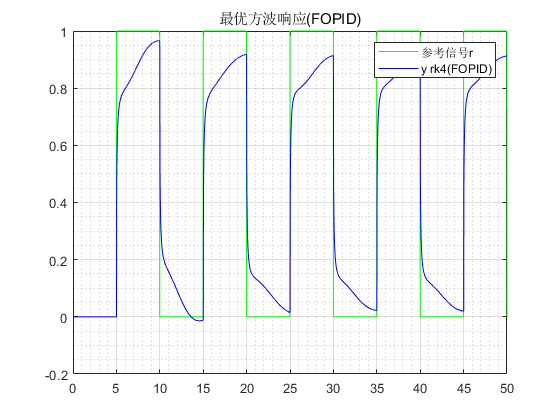


figure()
plot(t, r, 'g', T,gbest_output,'b') % X(1,:)为系统的输出
title("最优方波响应(FOPID)")
legend("参考信号r","y rk4(FOPID)")
grid on
grid minor

粒子群算法寻参效果不佳，猜测是因为陷入了局部最优，但目前没想到解决办法。

粒子群算法也可通过Matlab内置函数[`particleswarm()`](https://www.mathworks.com/help/releases/R2022a/gads/particleswarm.html?searchHighlight=pso&s_tid=doc_srchtitle#d123e60264)

function [mse, input, output] = calculate(x)
    % 初始化FOPID
    Kp = x(1);
    Ki = x(2);
    Kd = x(3);
    lammda = x(4);
    mu = x(5);
    L = 10;

    global sum_e e_last tau T X0 h r
    sum_e = 0;     
    e_last = 0;
    
    %%%%%%%% 使用龙格库塔法求解系统响应 %%%%%%%%
    N=length(T);
    X=zeros(length(X0),N);
    X(:,1)=X0;
    err = zeros(length(X0), N);
    input = zeros(length(X0),1);
    for i =2:N        
        X_k = X(:,i-1);
        t_k = T(i-1);
        
        if mod(t_k, tau) <=5
            ref = 0;
        else
            ref = 1;
        end
        
        err(:, i) = ref - X_k;
%         if abs(ref - X_k)/ref > 2.0 % 超调过大视为不稳定
%             disp('系统不稳定');
% %             X=inf*ones(length(X0),N);
%             break;
%         end
        u = fopid(err(1,:), Kp, Ki, Kd, lammda, mu, h, L/h, i);    % 只控制状态量X1
        input(i) = u;

        K1=fnc(t_k,X_k, u);
        K2=fnc(t_k+h/2,X_k+h/2*K1, u);
        K3=fnc(t_k+h/2,X_k+h/2*K2, u);
        K4=fnc(t_k+h,X_k+h*K3, u);
        
        X(:,i)=X_k + h/6*(K1+2*K2+2*K3+K4);
    end
    
    output = X(1,:)';
    e = r - output;
    % 均方误差
    mse = sum(e.^2)/length(e);
    % 平均误差
%     e = abs(e);
%     mse = sum(e)/length(e);
end
    
function dx = fnc(t, x, u)
    global Wn zeta
    dx = zeros(length(x), 1);
    dx(1) = x(2);
    dx(2) = -Wn^2*x(1) - 2*zeta*Wn*x(2) + Wn^2*u;
end
